# Activity 2. Fourier Transformation Model of Image Formation

### Manalang, Johnenn R. | Applied Physics 157 

## Activity 2.1. Familiarization with Discrete FT

Create an image of a white circle against a black background centered in a 400x400 pixel matrix. Apply fft2() on the image and compute the intensity values using abs(). Use fftshift to make the FFT2 output appear zero-centered then display. Use the "hot" colormap to make it look like a laser diffraction pattern.

#### Circle Aperture 

r = 0.1

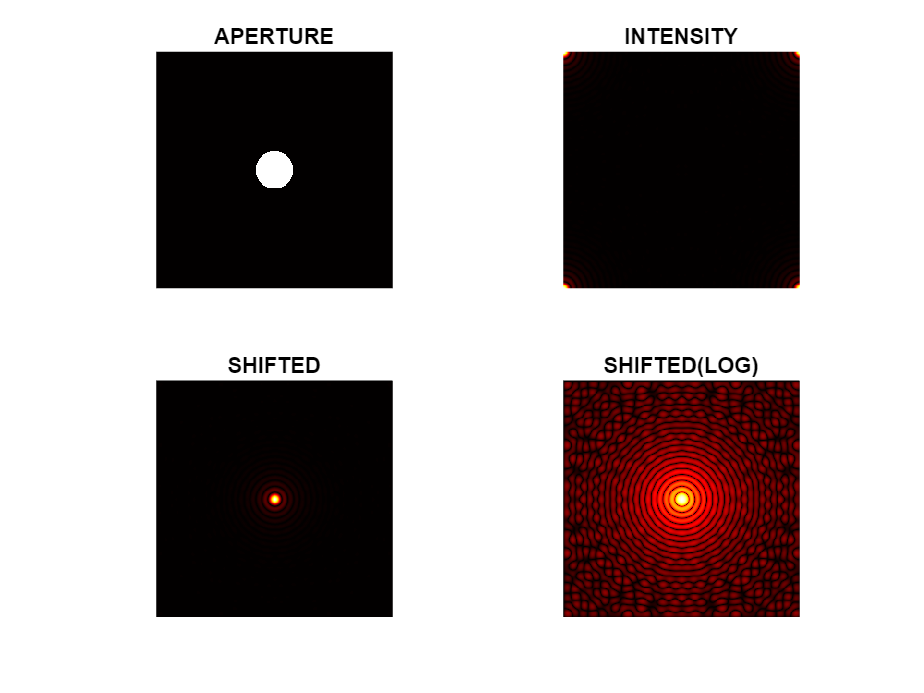

clear; close;
FFT(Circle(0.1));

r = 0.05

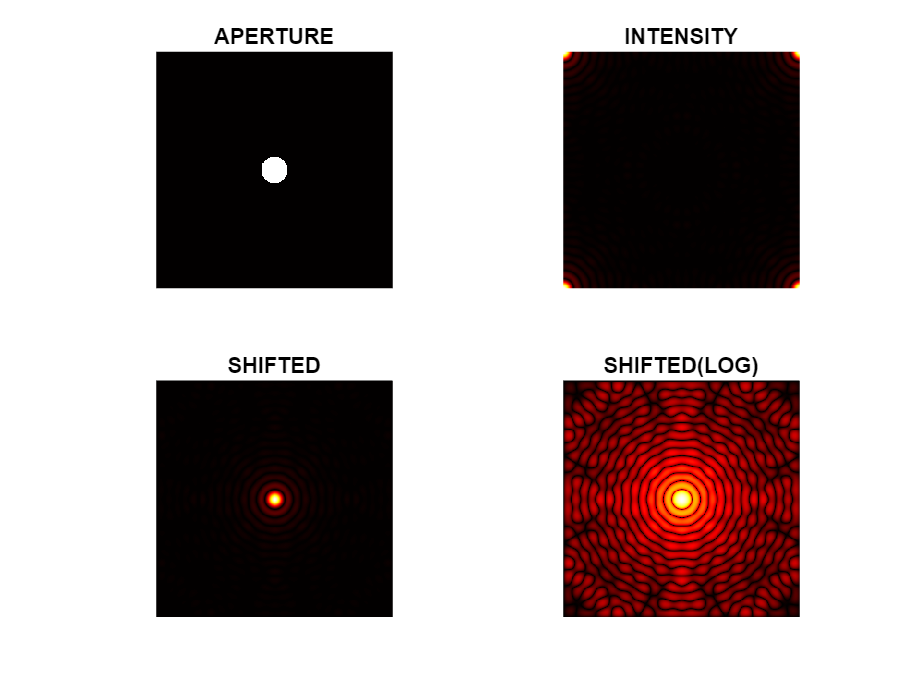

FFT(Circle(0.05));

r = 0.01

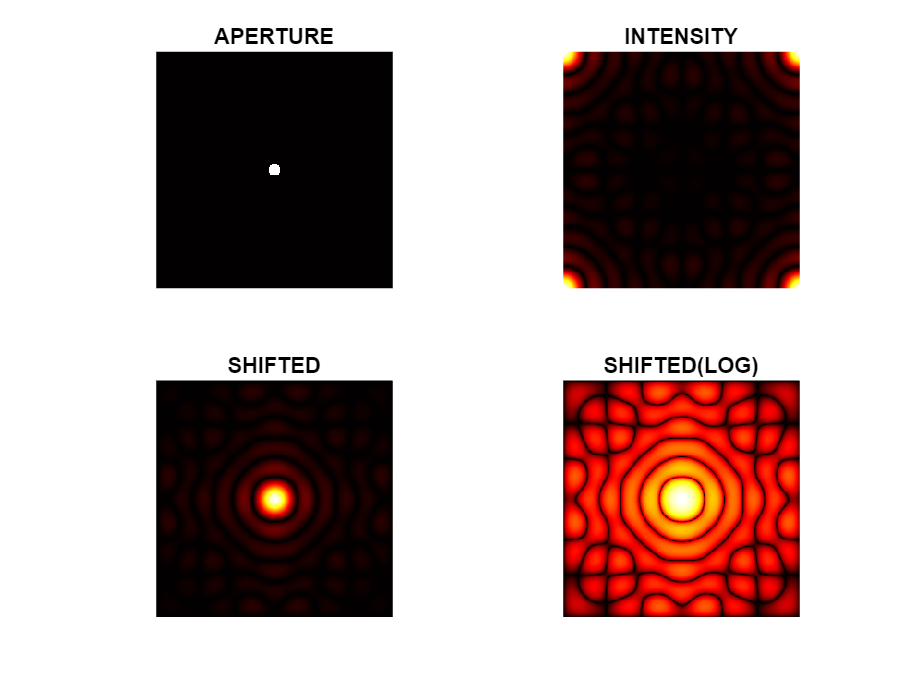

FFT(Circle(0.01));

r = 0.005

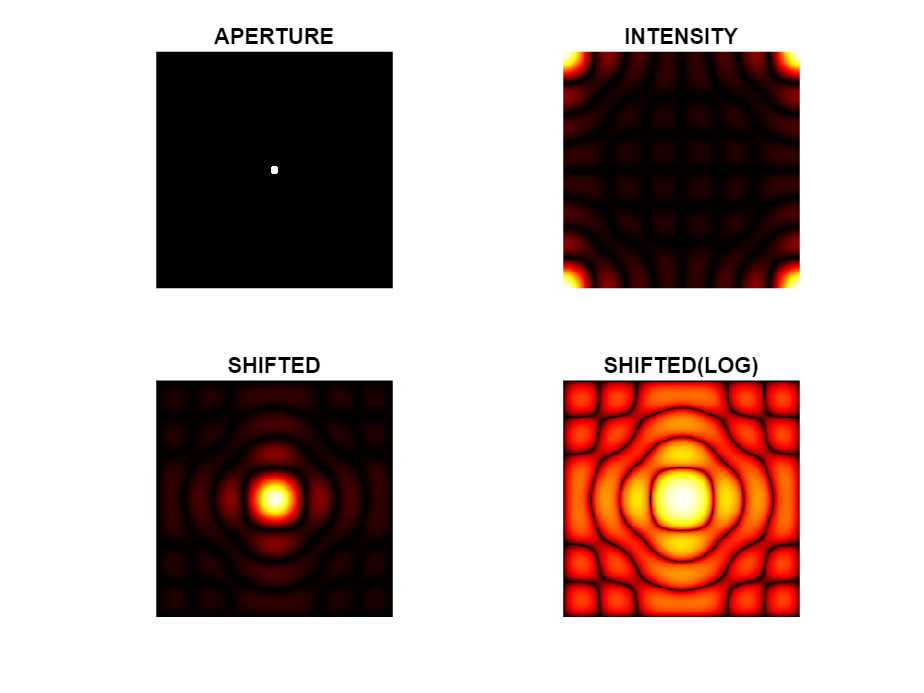

FFT(Circle(0.005));

#### Sinusoidal Aperture

frequency = 5, angle of rotation = 0

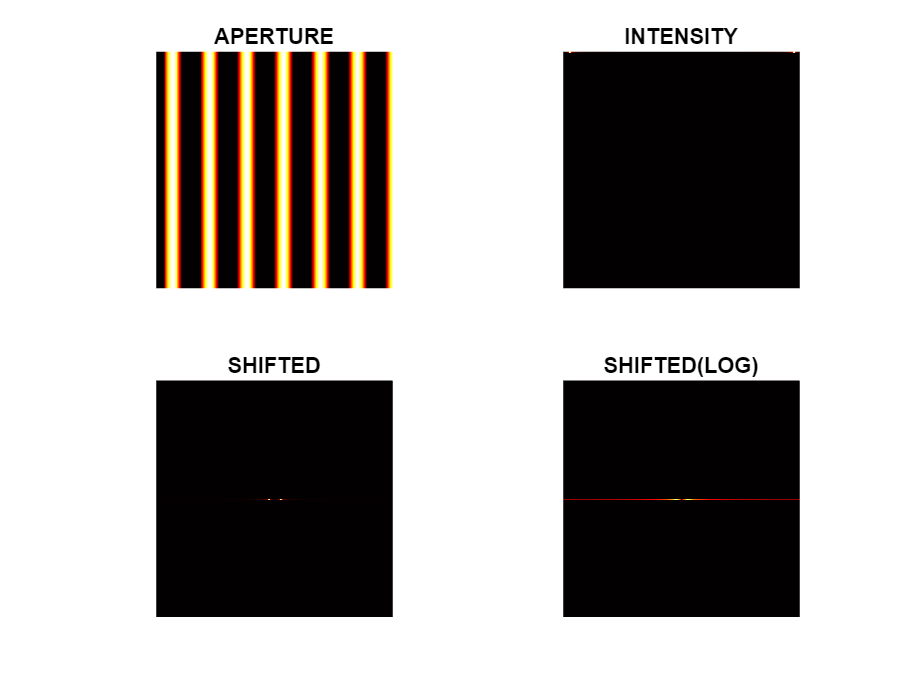

FFT(Sinusoid(5,0));

frequency = 15, angle of rotation = 0

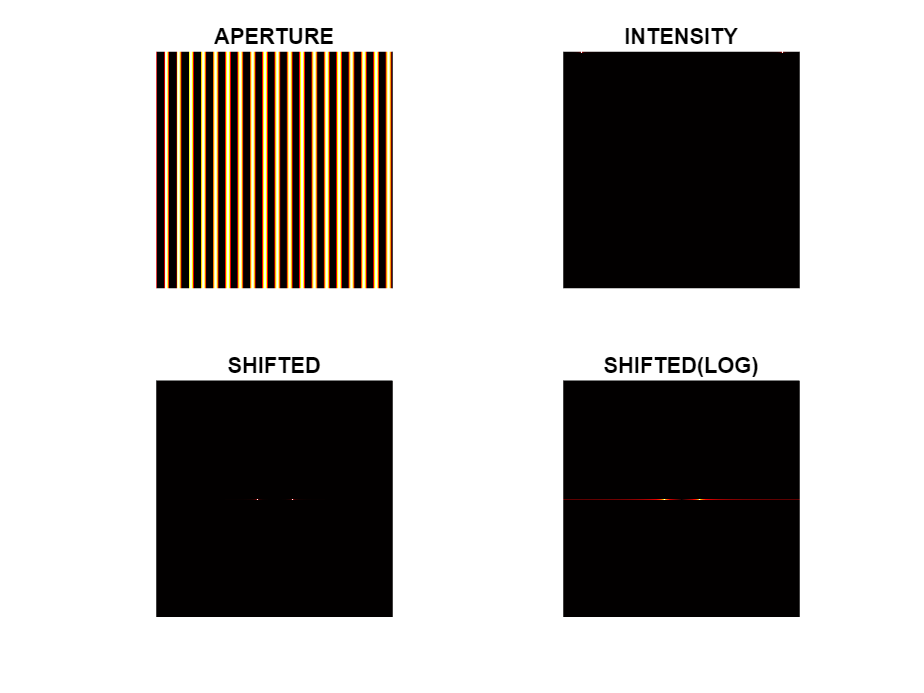

FFT(Sinusoid(15,0));

frequency = 20, angle of rotation = 0

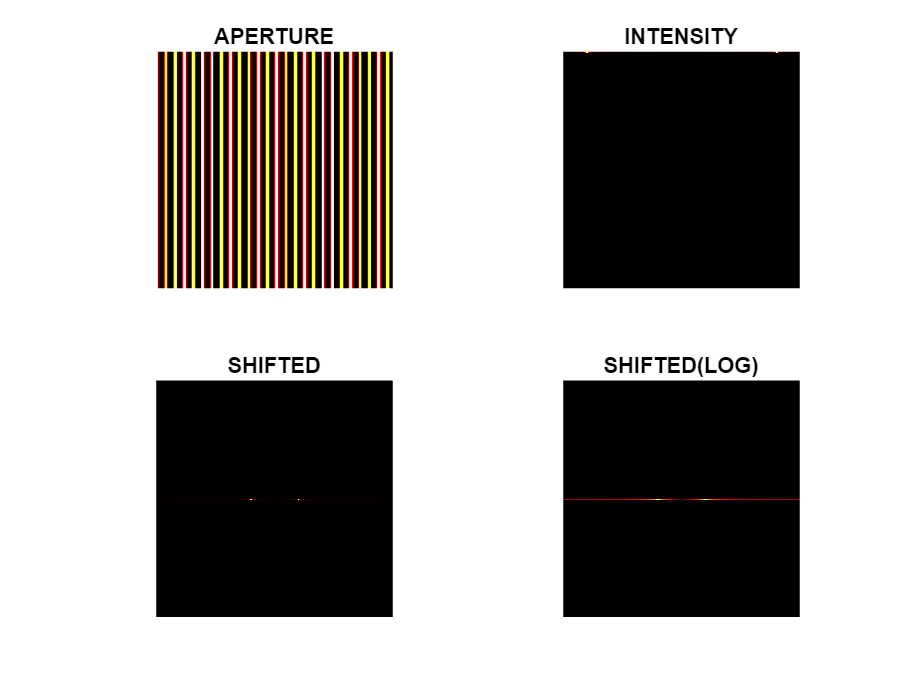

FFT(Sinusoid(20,0));

frequency = 20, angle of rotation = 90

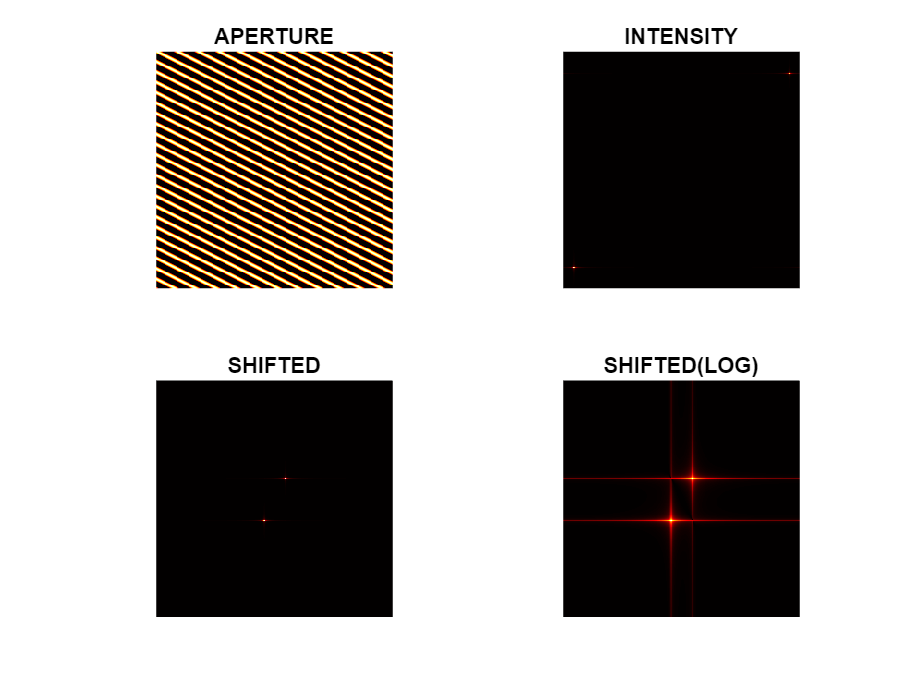

FFT(Sinusoid(20,90));

frequency = 20, angle of rotation = 180

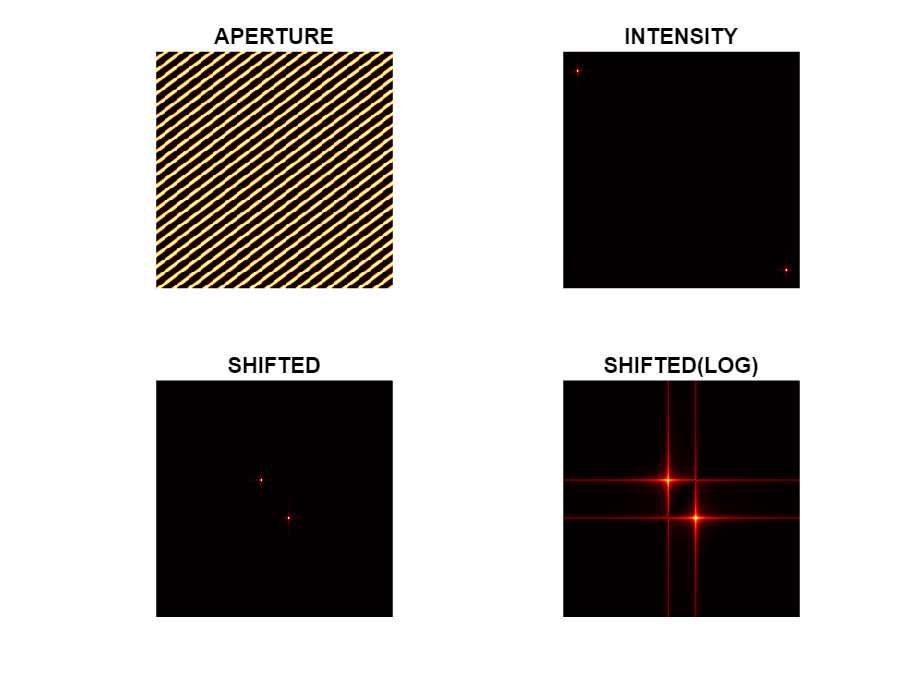

FFT(Sinusoid(20,180));

#### Rectangular aperture

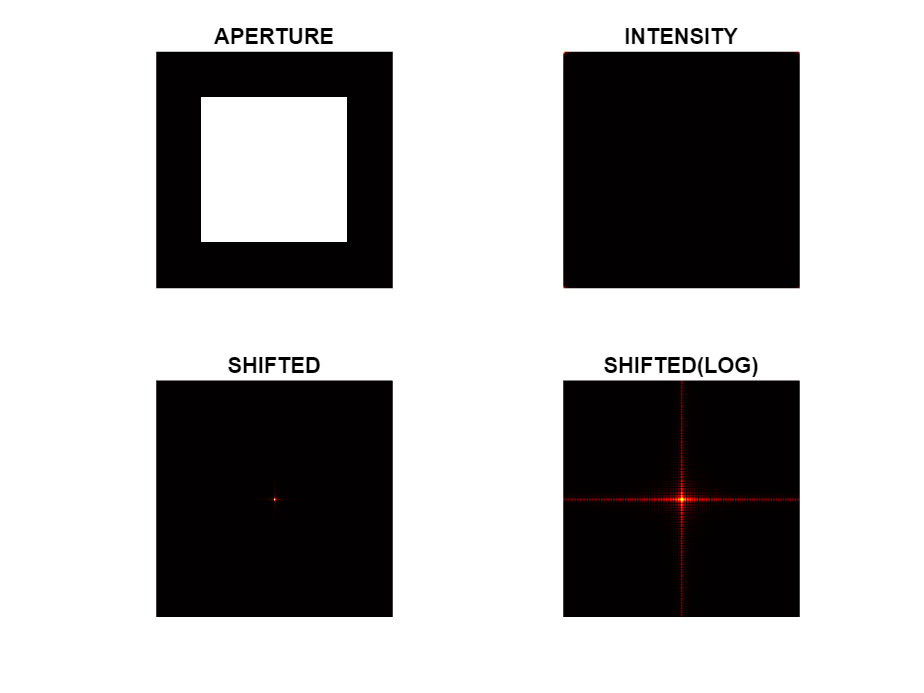

FFT(Rectangle(50,206,50,206));

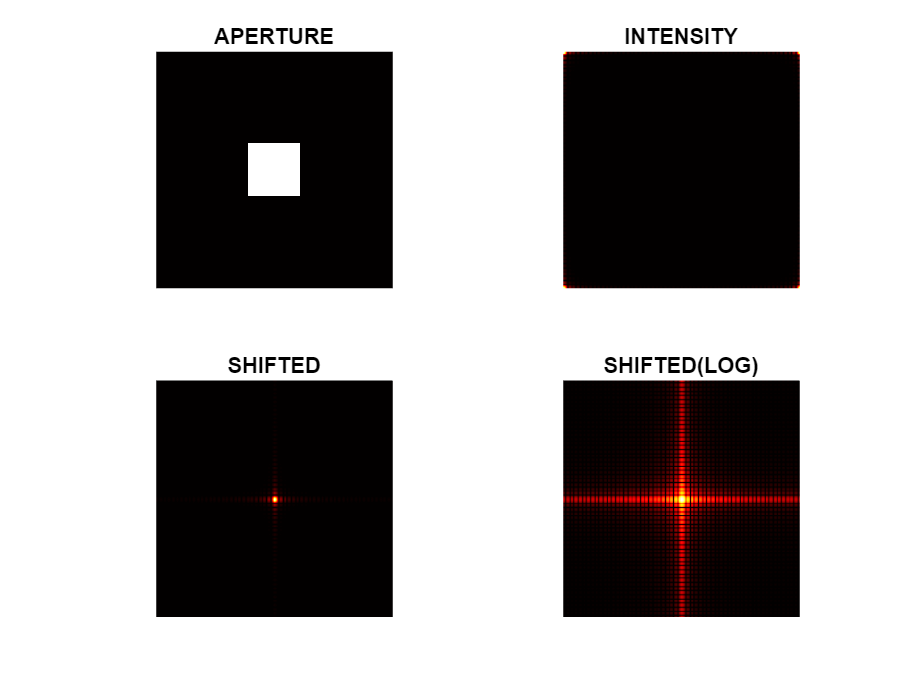

FFT(Rectangle(100, 156,100,156));

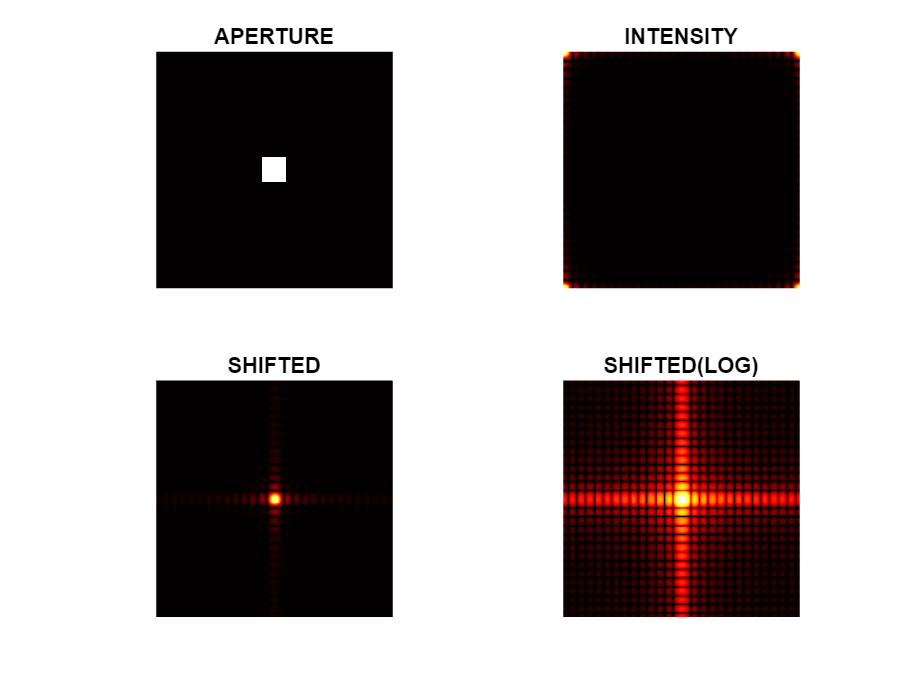

FFT(Rectangle(115,141,115,141));

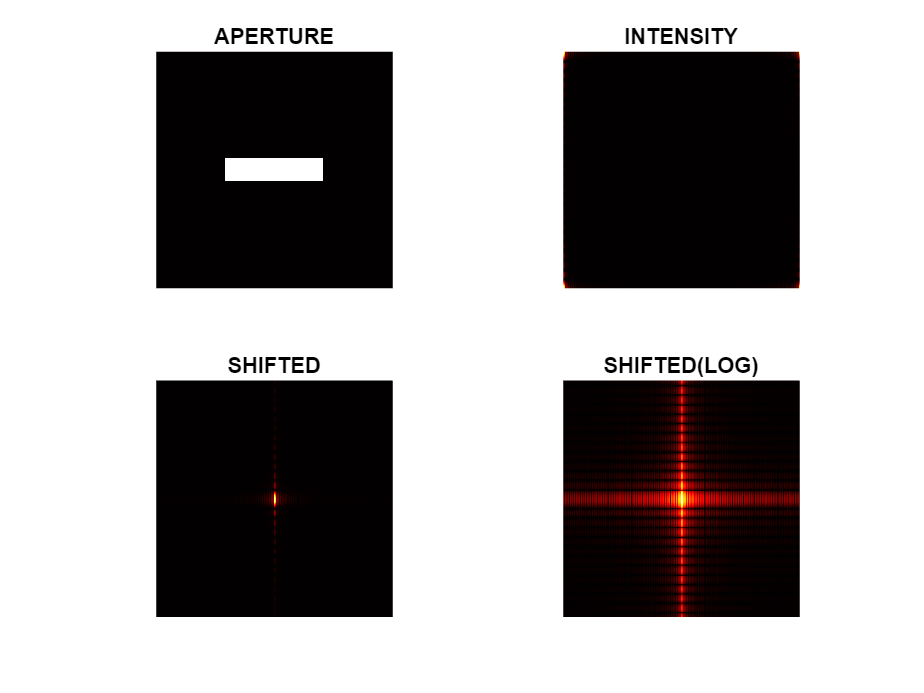

FFT(Rectangle(116,140,75,181));

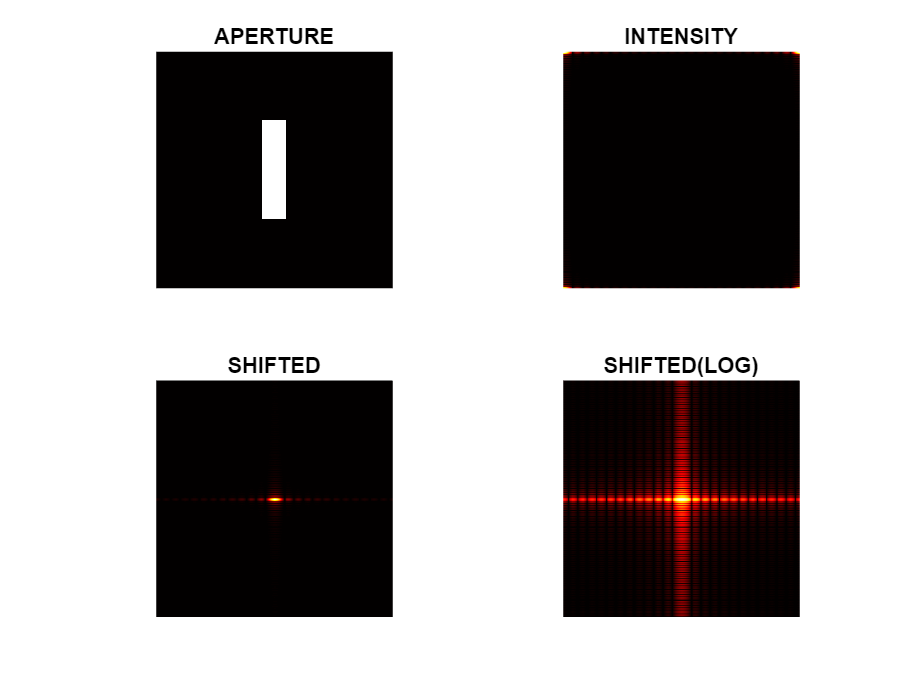

FFT(Rectangle(75,181,116,140));

#### Double Slit Aperture

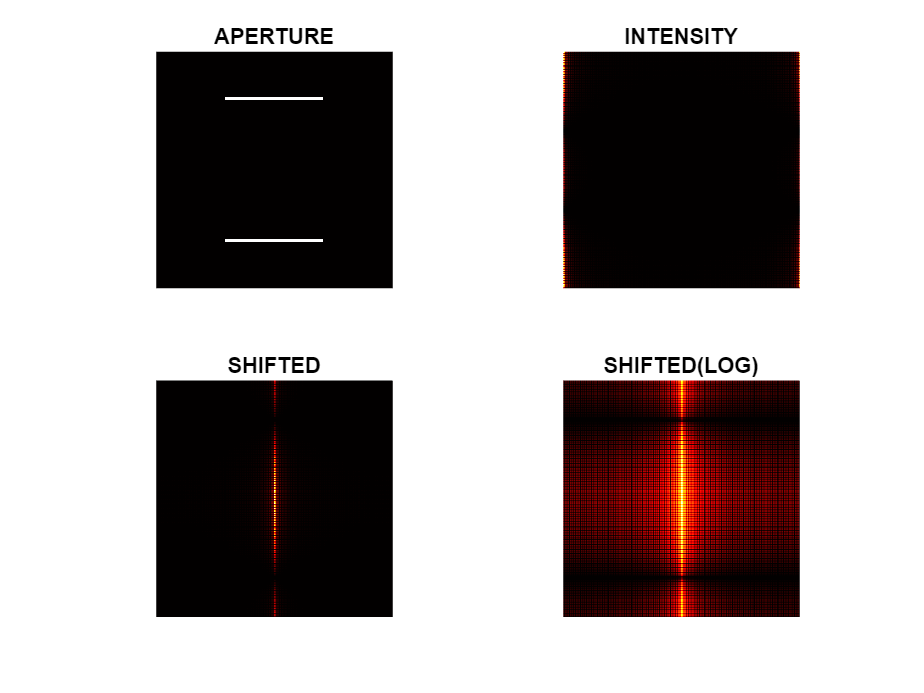

FFT(Slit(50, 52, 75,181, 204,206, 75,181));

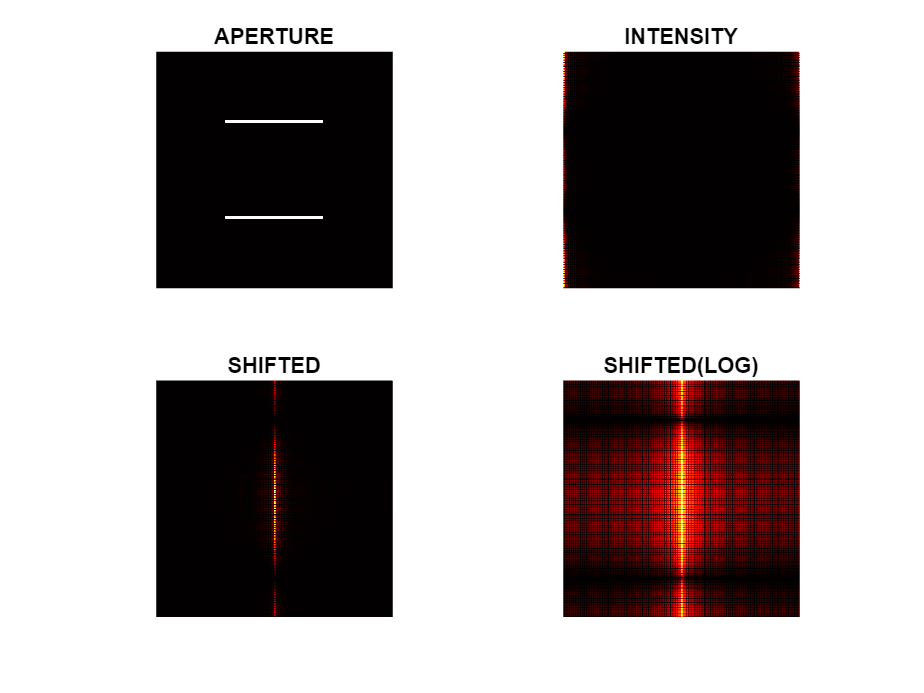

FFT(Slit(75, 77, 75,181, 179, 181, 75,181));

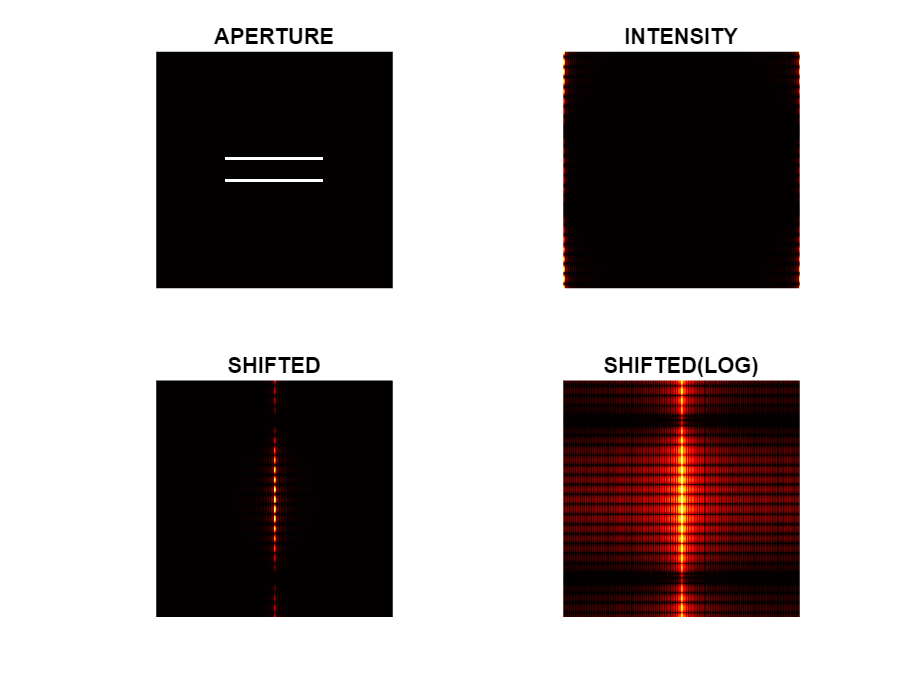

FFT(Slit(115, 117, 75,181, 139 ,141, 75,181));

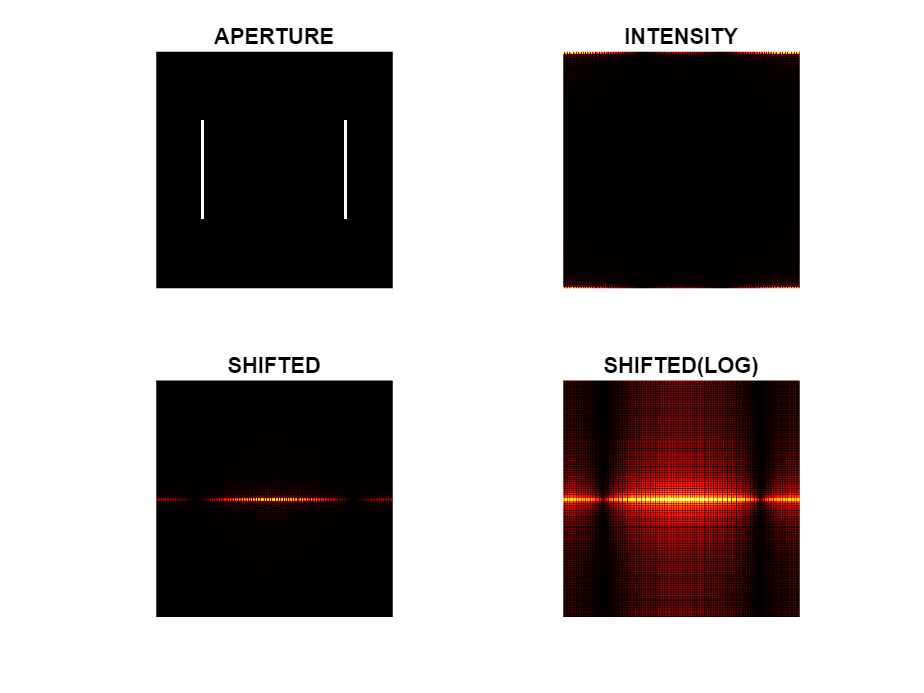

FFT(Slit(75,181,50, 52, 75,181, 204,206));

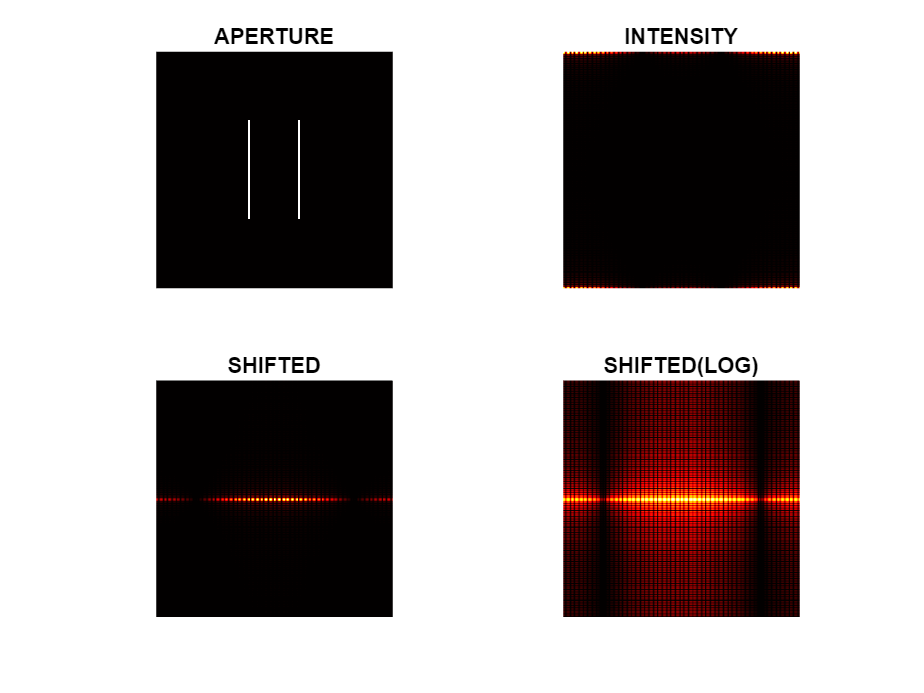

FFT(Slit(75,181,100, 102, 75,181, 154, 156));

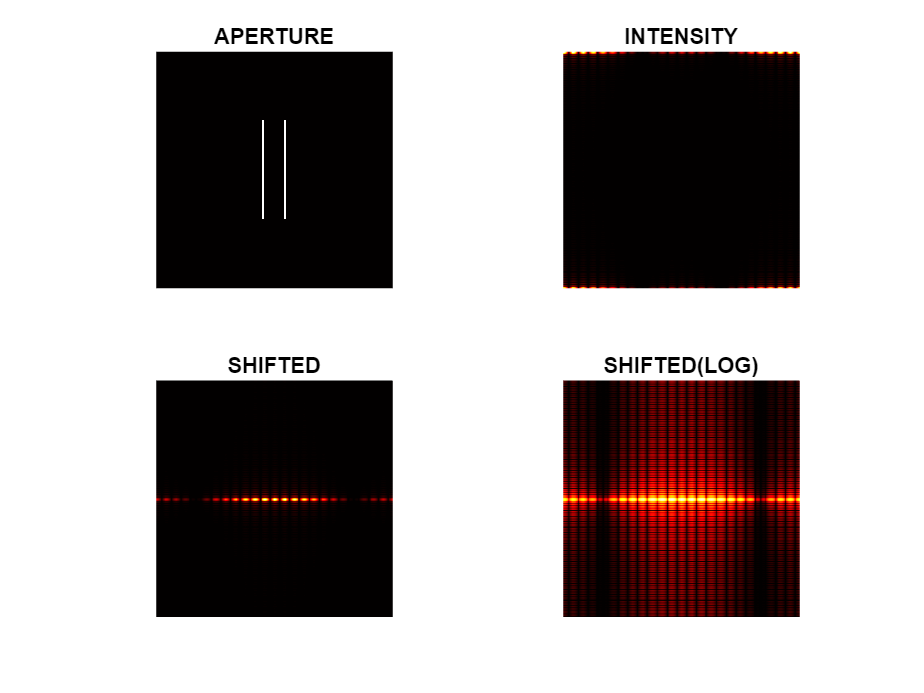

FFT(Slit(75,181,115,117,75,181,139,141));

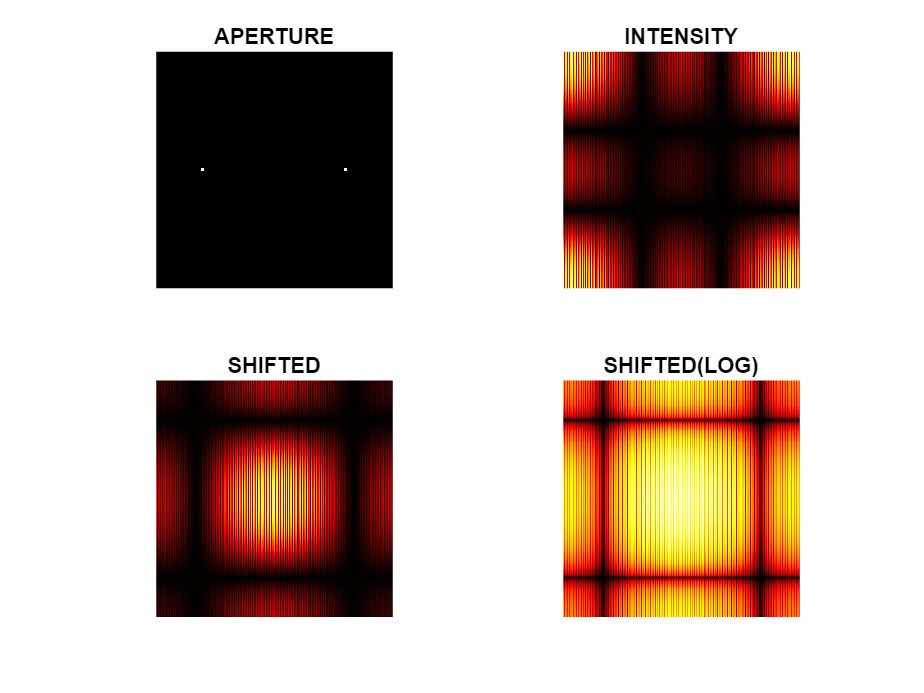

FFT(Slit(127, 129,50, 52, 127, 129, 204, 206));

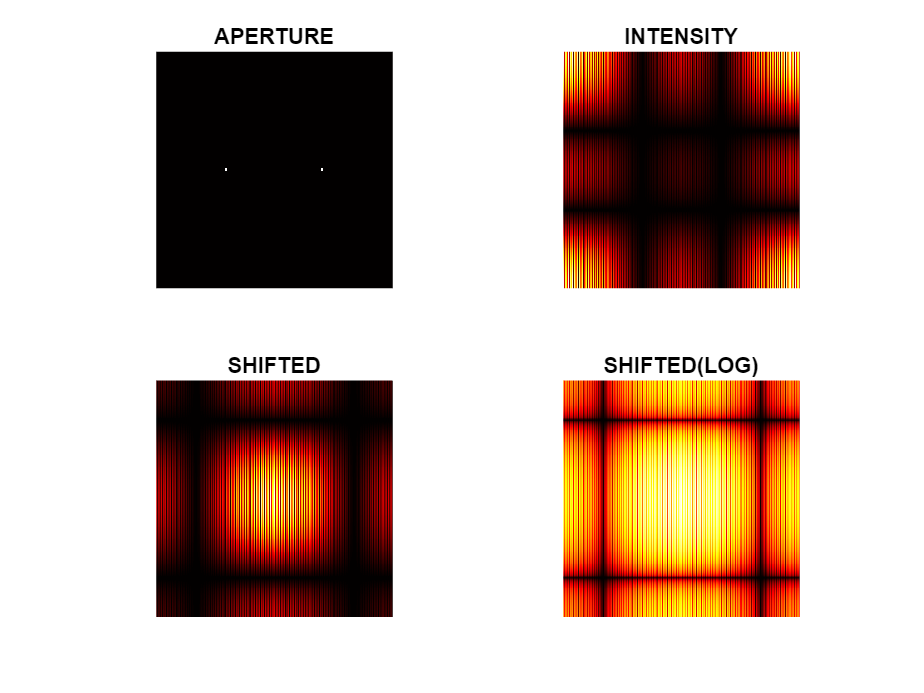

FFT(Slit(127, 129,75, 77, 127, 129, 179, 181));

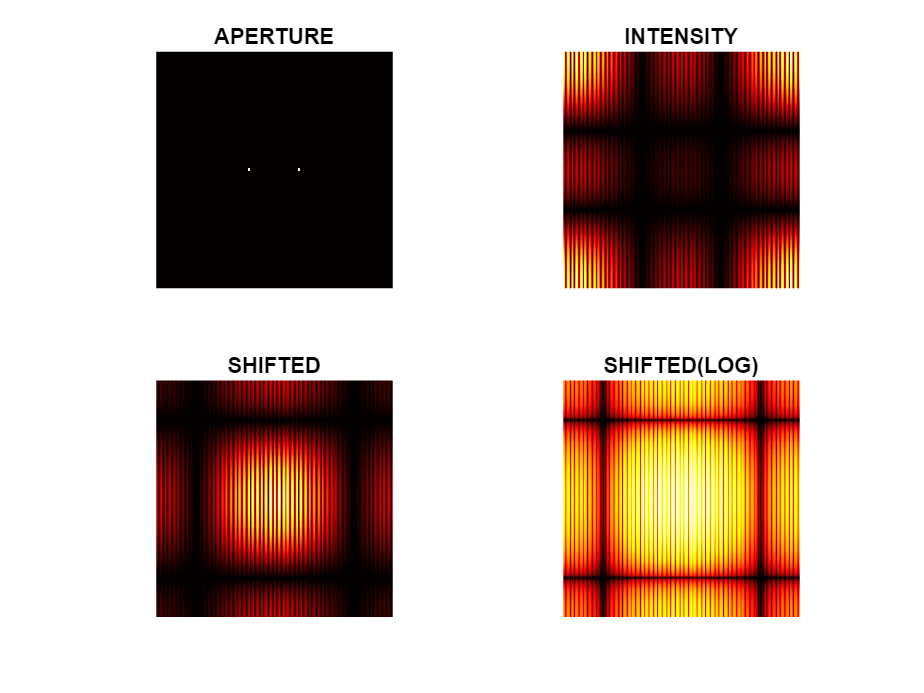

FFT(Slit(127, 129,100, 102, 127, 129, 154, 156));

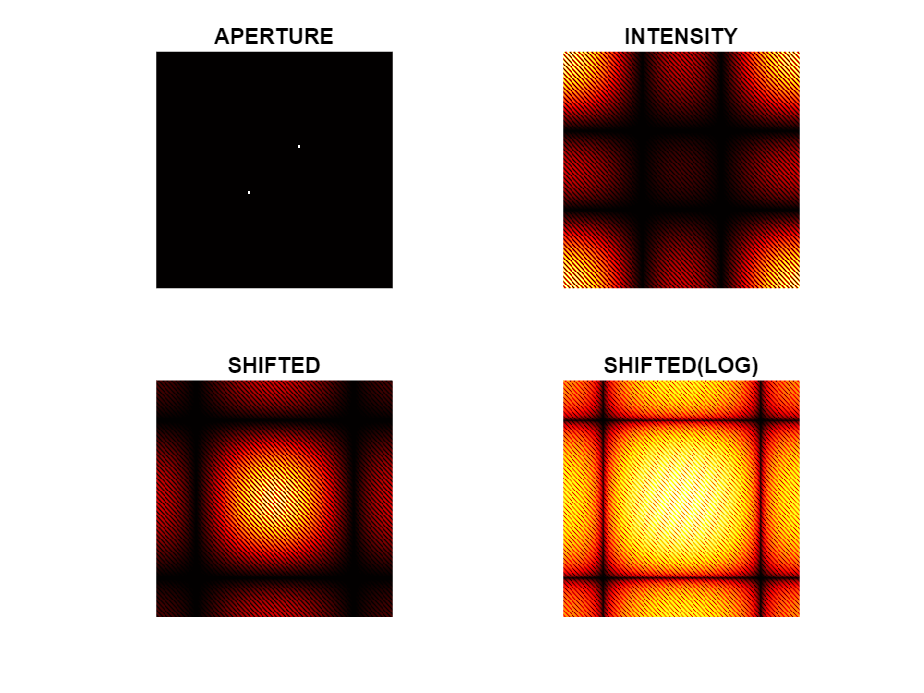

FFT(Slit(152, 154,100, 102, 102, 104, 154, 156));

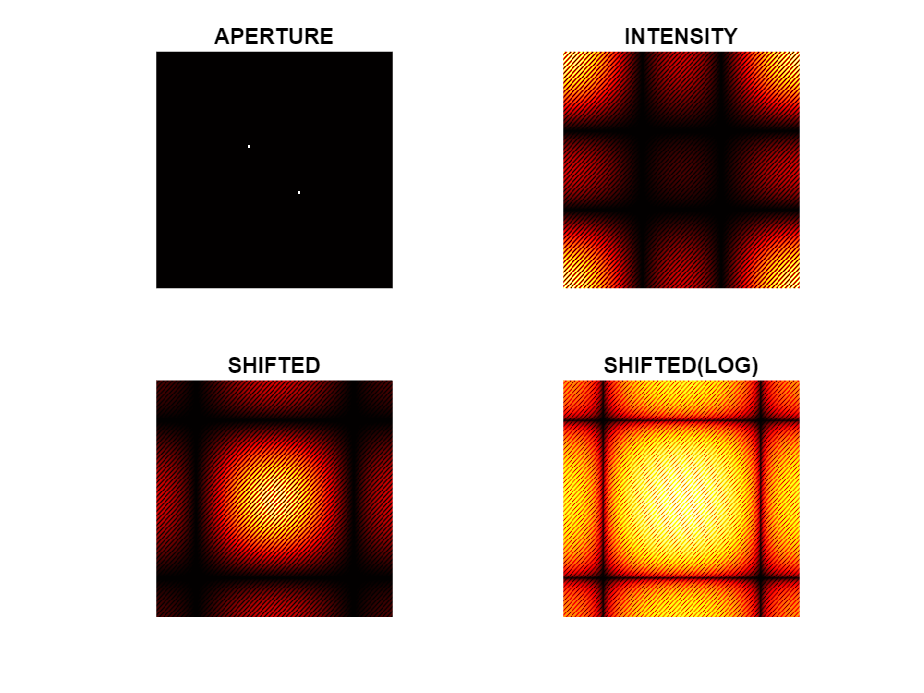

FFT(Slit(102, 104,100, 102, 152, 154, 154, 156));

4. Load the image in your program and convert this image into grayscale. Apply fft2() twice on the image and display the reconstruction. Do it again, but this time apply fft() followed by ifft2(). Comment on the appearance of the reconstructed images. 

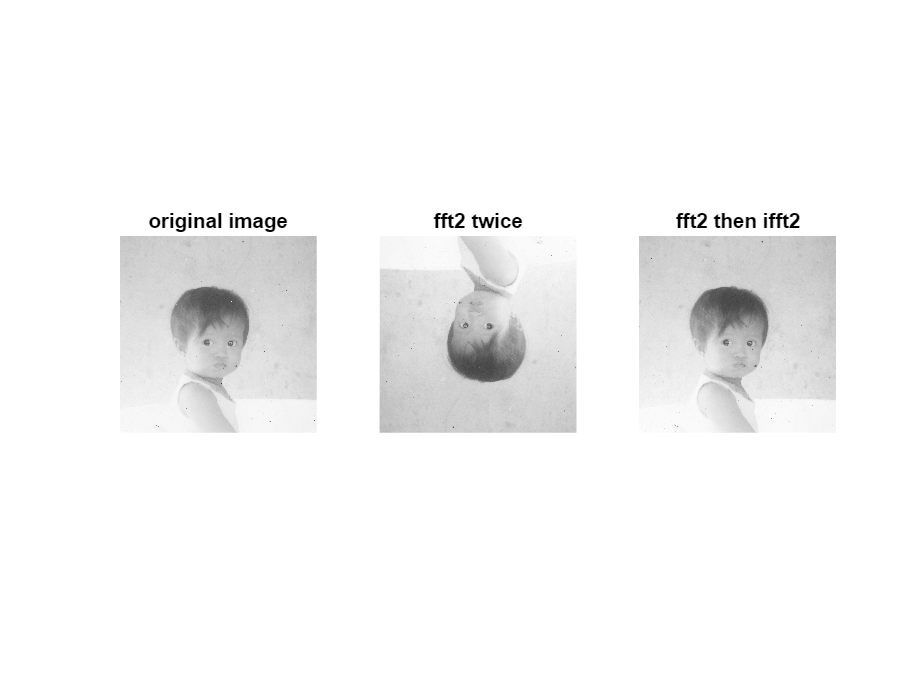

clear; close all;
%Load image
I = rgb2gray(imread('squarejanen.jpg'));

%perfom fft2 twice
Irec = fft2(fft2(I));
Irecmag = abs(Irec);

%Apply fft2 then ifft2
Irec2 = ifft2(fft2(I));
Irec2mag = abs(Irec2);

%plotting
subplot (1,3,1); imshow(I); title("original image");
subplot(1,3,2); imagesc(Irecmag); colormap gray; axis image; axis off; title("fft2 twice");
subplot(1,3,3);imagesc(Irec2mag); colormap gray; axis image; axis off; title("fft2 then ifft2");

Trying to see what the FT of the image is.

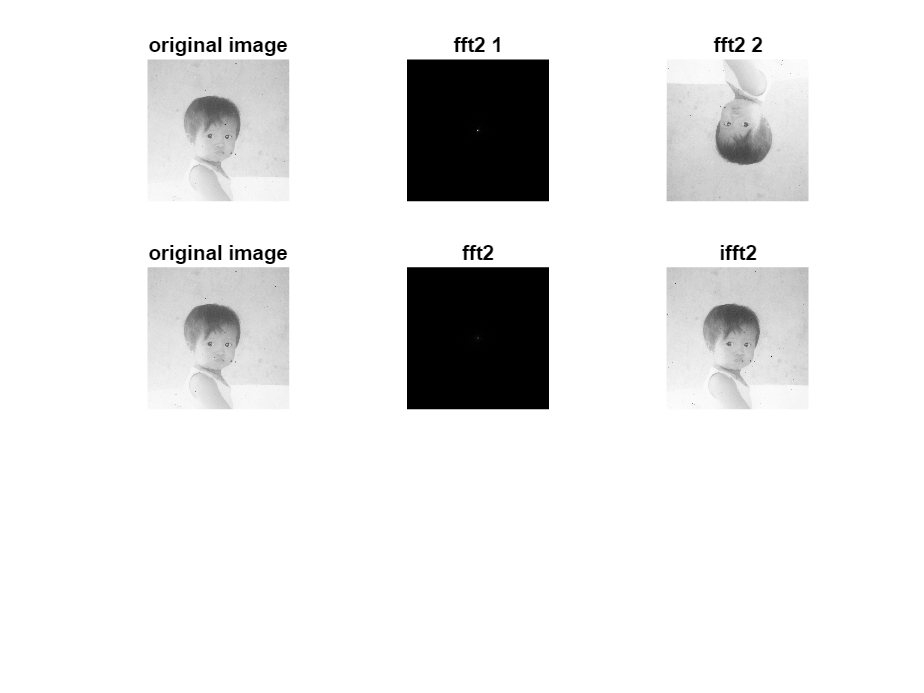

clear; close all;
%Load image
I = rgb2gray(imread('squarejanen.jpg'));

%perfom fft2 twice
FFT1 = fft2(I);
FFTmag = abs(FFT1);
FFTshifted = fftshift(FFT1);
FFTmagshift = rescale(abs(FFTshifted), 0, 256);
FFTT =fft2(fft2(I));

%Apply fft2 then ifft2
FFT3 = fft2(I);
FFTmag1 = abs(FFT3);
FFTshifted1 = fftshift(FFT3);
FFTmagshift1 = rescale(abs(FFTshifted1), 0, 256);
FFTT1 = ifft2(fft2(I));

%plotting
subplot (3,3,1); imshow(I); title("original image");
subplot(3,3,2); imshow(FFTmagshift); colormap hot; axis image; axis off; title("fft2 1");
subplot(3,3,3);imagesc(abs(FFTT)); colormap gray; axis image; axis off; title("fft2 2");
subplot (3,3,4); imshow(I); title("original image");
subplot(3,3,5); imshow(FFTmagshift1); colormap hot; axis image; axis off; title("fft2");
subplot(3,3,6);imagesc(abs(FFTT1)); colormap gray; axis image; axis off; title("ifft2");

## Activity 2.2. Simulation of an Imaging System

The fourier transform (FT) of the NIP image. 

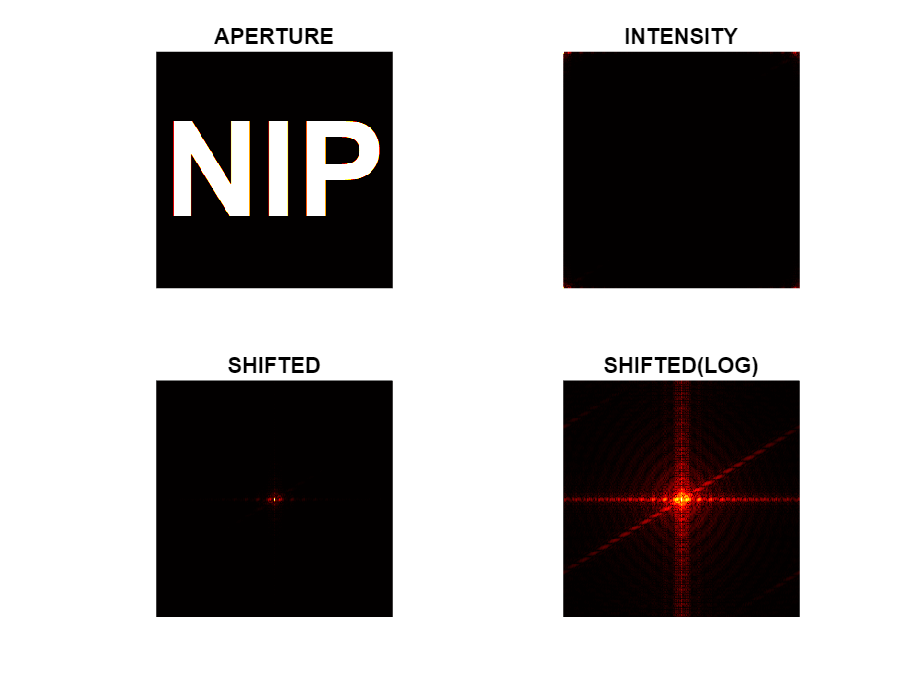

clear; close;
I = rgb2gray(imread('nip.tif'));
FFT(I);

circle = 10% of the 256x256 image

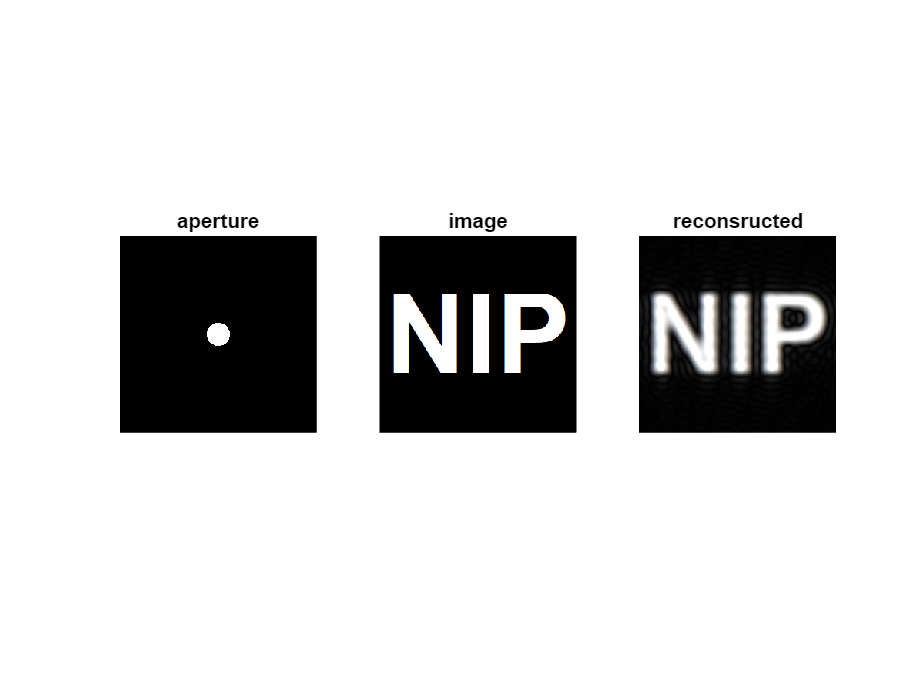

clear; close all; 
Convolution('circle.tif');

circle = 25% of the 256x256 image

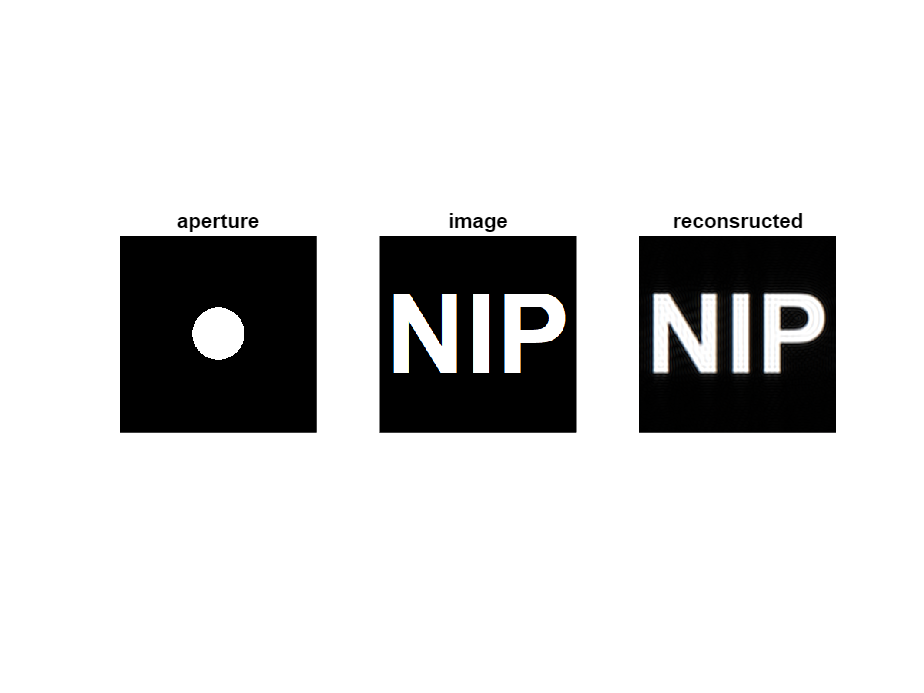

clear; close all; 
Convolution('circle25.tif');

circle = 50% of the 256x256 image

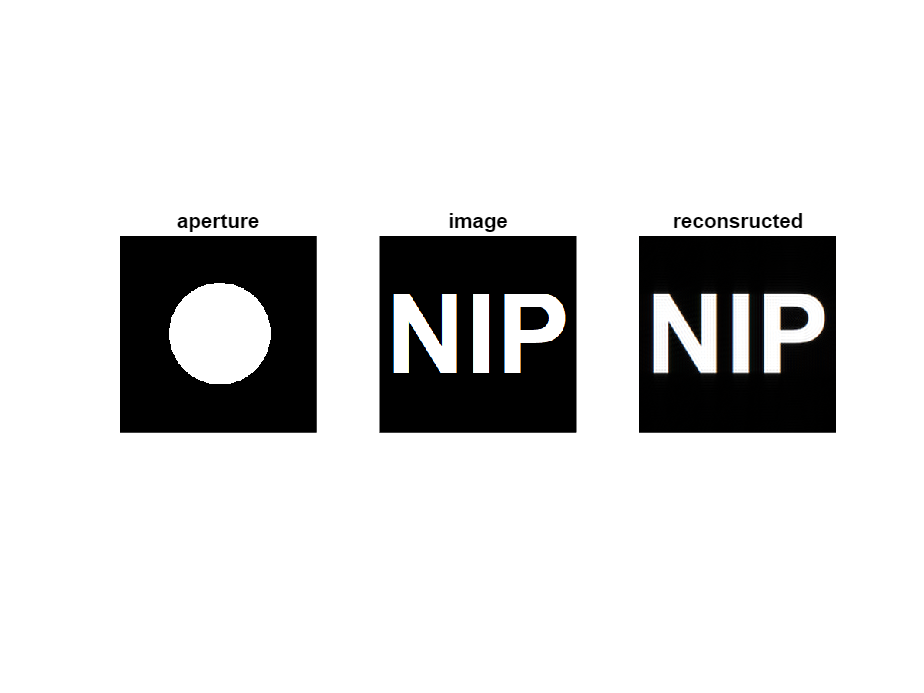

clear; close all; 
Convolution('circle50.tif');

circle = 75% of the 256x256 image

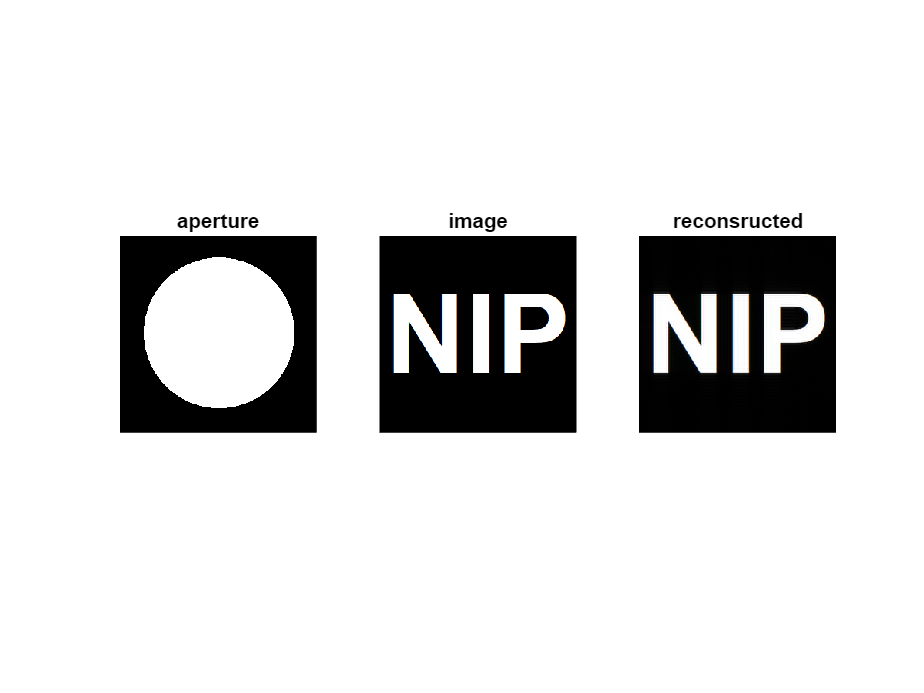

clear; close all; 
Convolution('circle75.tif');

circle = 100% of the 256x256 image

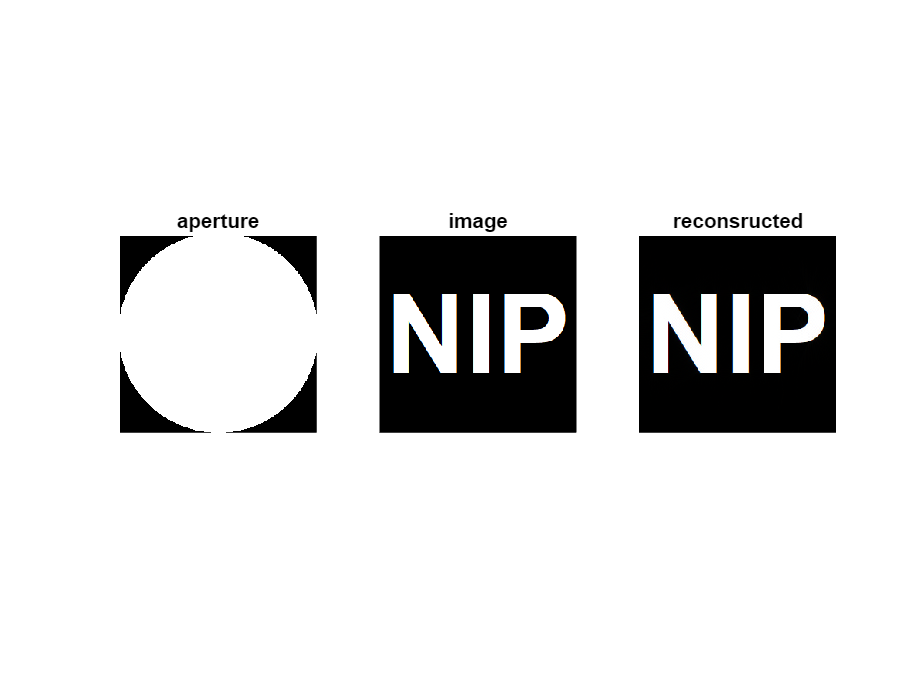

clear; close all; 
Convolution('circle100.tif');

#### James Webb Space Telescope

Simulating the image of a start as seen by the James Webb Space Telescope.

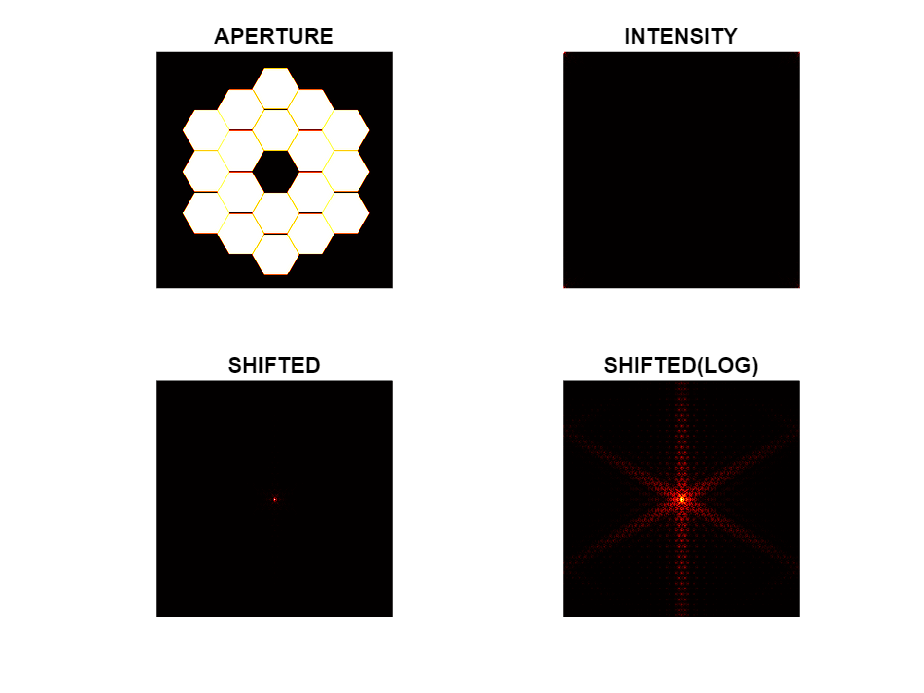

clear; close; 
A = rgb2gray(imread('jwst1.png'));
FFT(A);

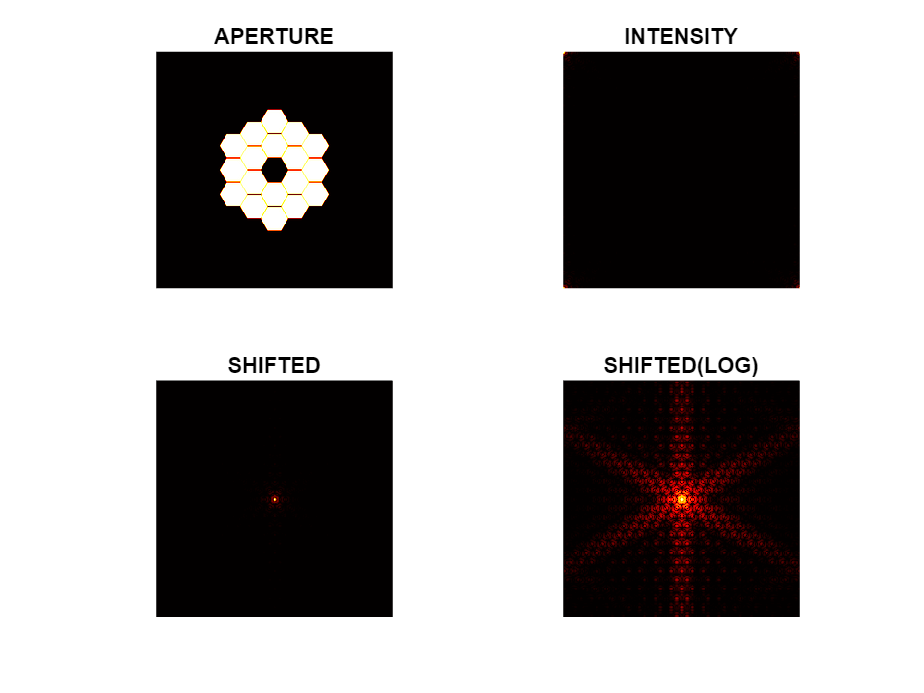

clear; close; 
A = rgb2gray(imread('jwst2.png'));
FFT(A);

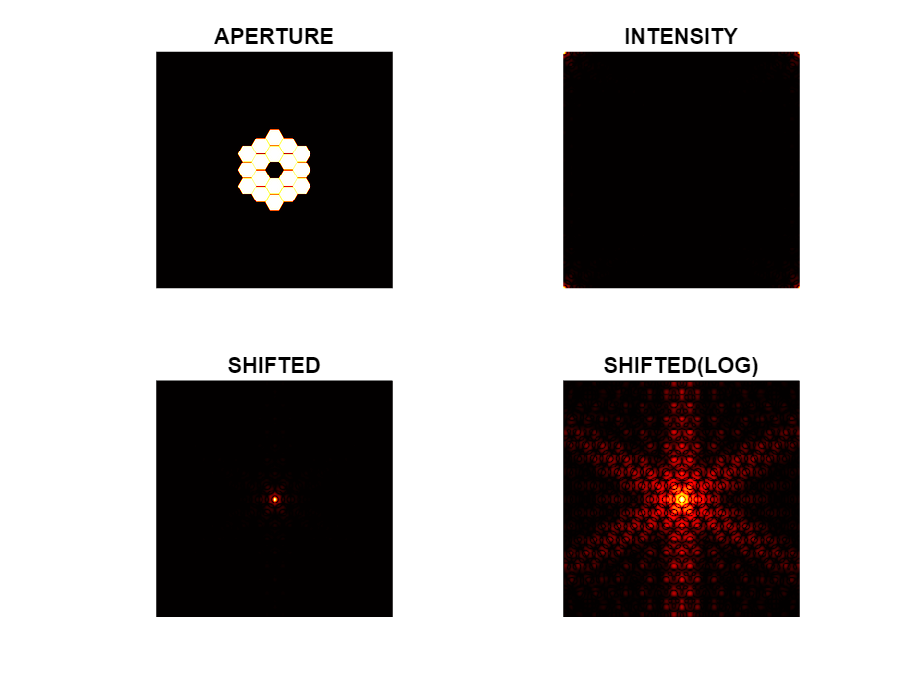

clear; close; 
A = rgb2gray(imread('jwst3.png'));
FFT(A);

JWST with the secondary mirror. 

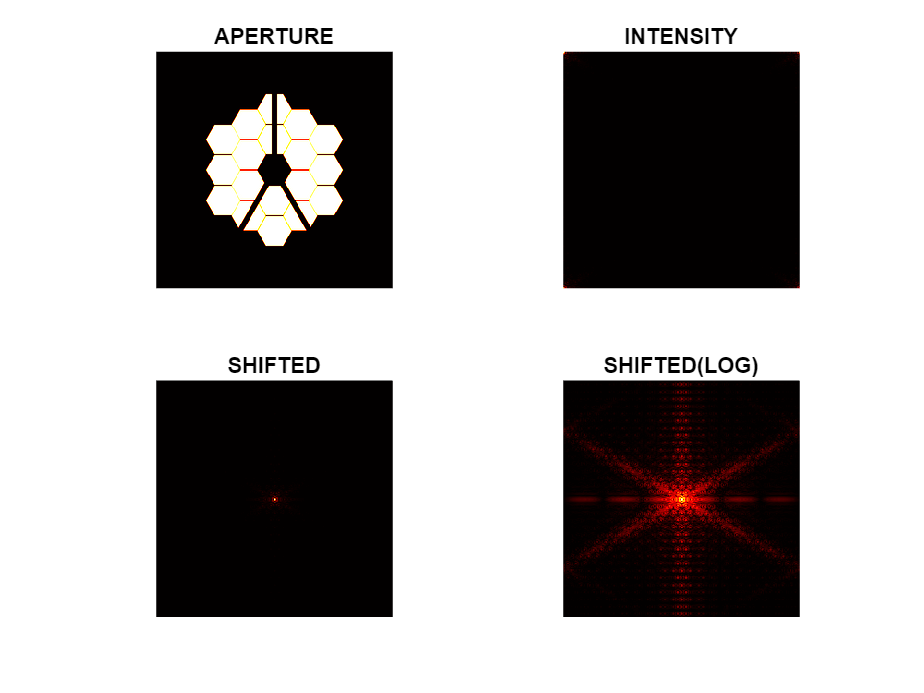

clear; close; 
A = rgb2gray(imread('jwstnew.png'));
FFT(A);

Using JWST as the aperture and NIP as the image.

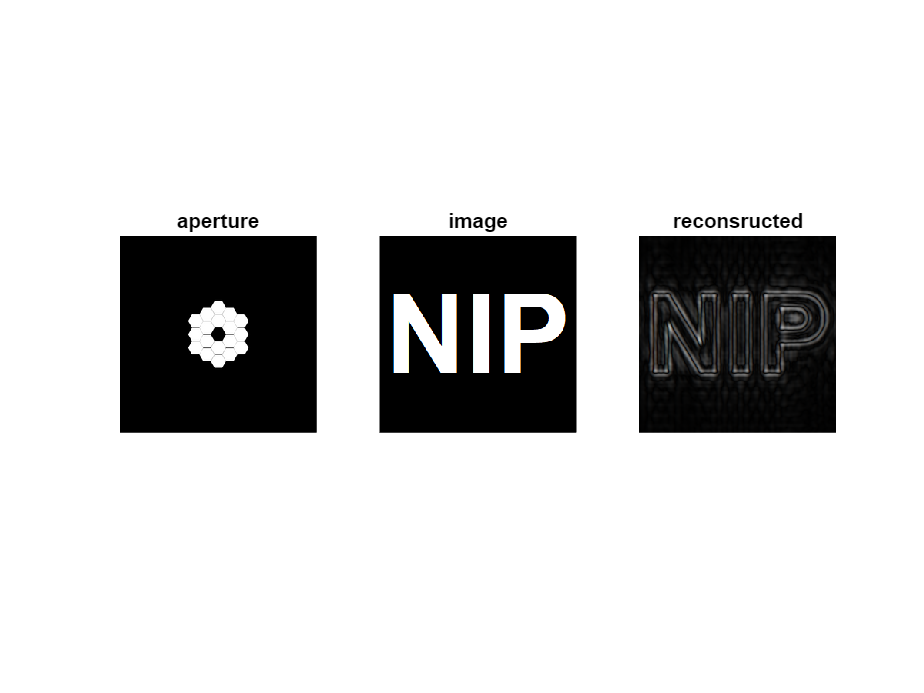

clear; close all; 
Convolution('jwst3.png');

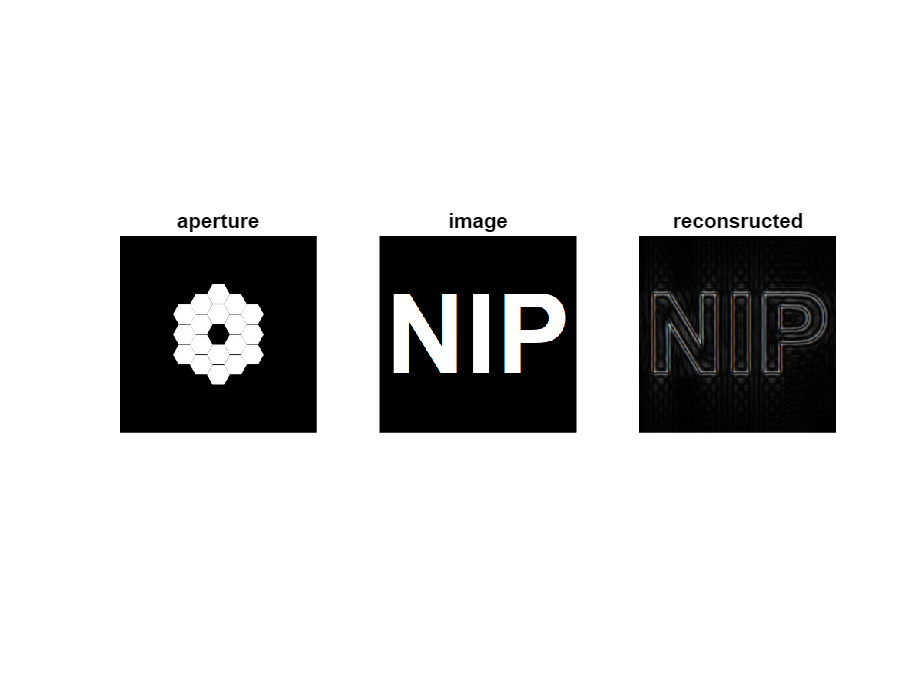

clear; close all; 
Convolution('jwst2.png');

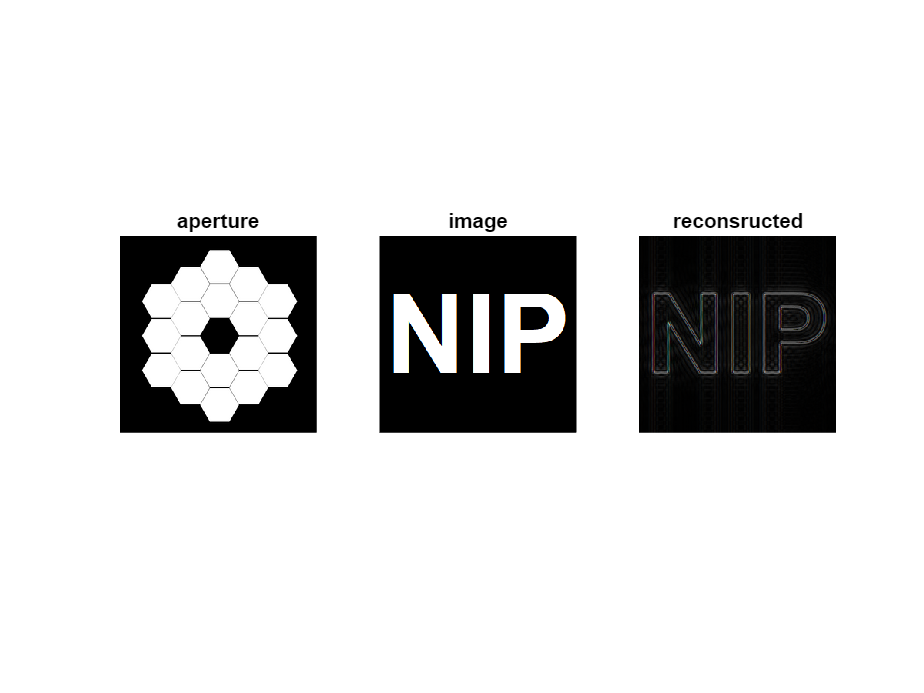

clear; close all; 
Convolution('jwst1.png');

## Activity 2.3. Template matching using correlation

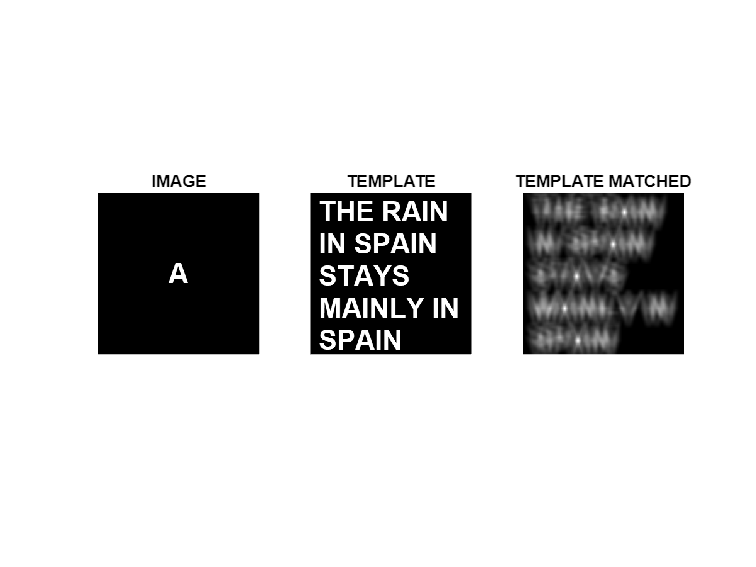

clear;close;
Correlation('A.tif', 'THERAIN.tif');

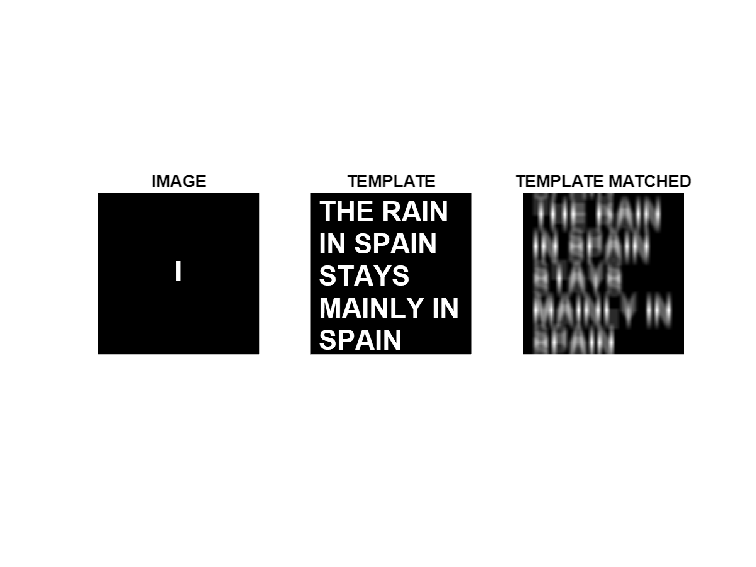

clear;close;
Correlation('I.tif', 'THERAIN.tif');

The famous Filipino tongue twister as the template. 

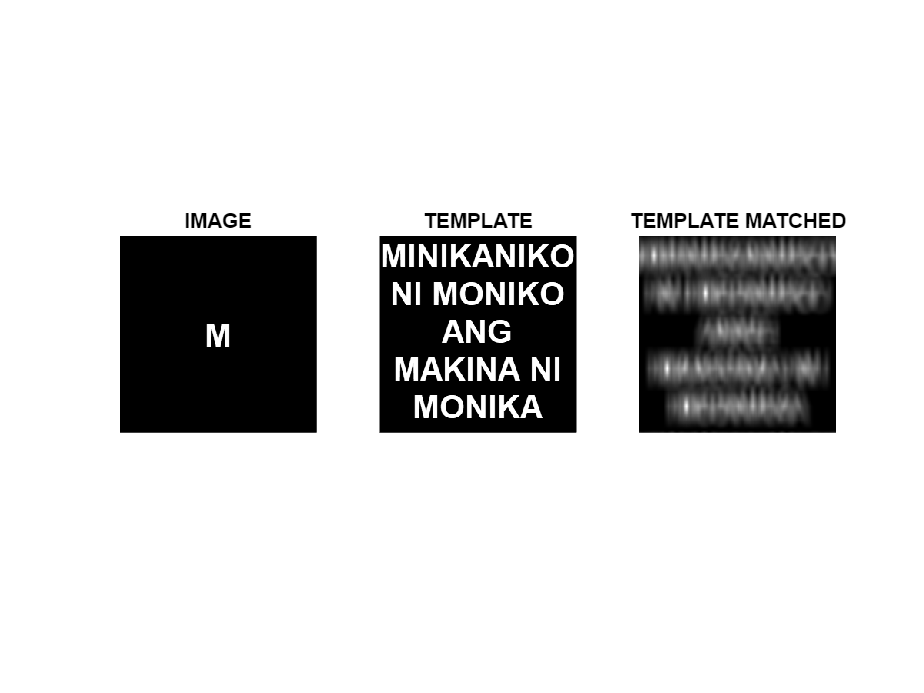

clear;close;
Correlation('M.tif', 'MINIKANIKO.tif');

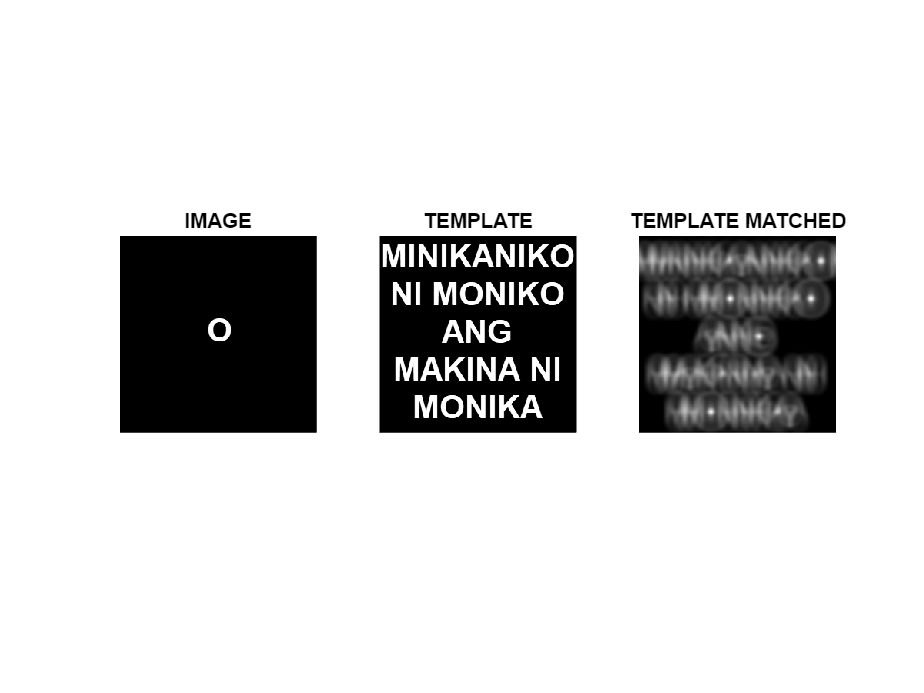

clear;close;
Correlation('O.tif', 'MINIKANIKO.tif');

Different shapes and sizes as the template. 

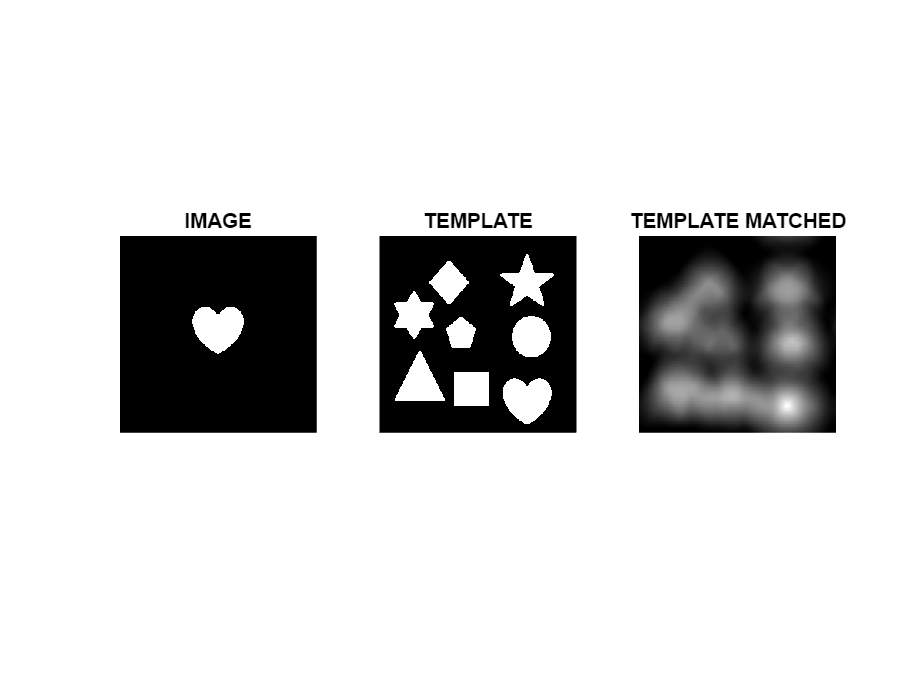

clear;close;
Correlation('heart.tif', 'shapes.tif');

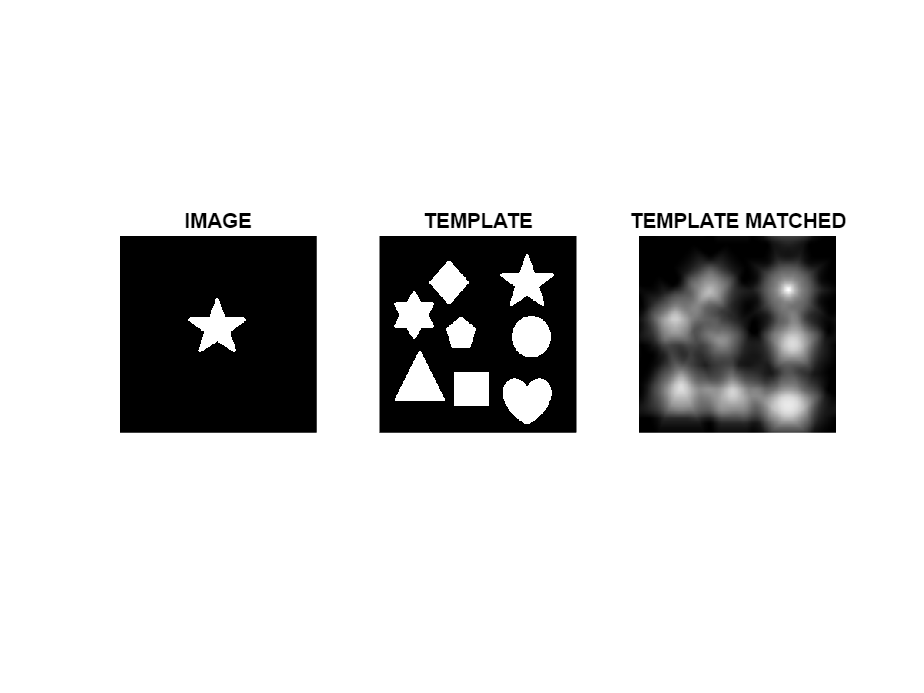

clear;close;
Correlation('star.tif', 'shapes.tif');

#### Functions 

Here are the functions that were used for the simulations. 

For Activity 2.1:

- FFT(aperture)

- Circle(r)

- Sinusoid(f,d)

- Rectangle(a,b,c,d)

- Slit(a,b,c,d,e,f,g)

For Activity 2.2:

- Convolution(aperture)

For Activity 2.3:

- Correlation(template, I)

function [a,b, c,d] = FFT(aperture)
    FFT = fft2(aperture);
    FFTmag = abs(FFT);
    FFTshifted = fftshift(FFT);
    FFTmagshift = rescale(abs(FFTshifted), 0, 256);
    FFTlog = log(FFTmagshift+1);
    FFTres = rescale(FFTlog, 0, 256);
    a = subplot(2,2,1); imshow(aperture); title("APERTURE");
    b = subplot(2,2,2); image(rescale(FFTmag,0,256)); colormap hot; title("INTENSITY"); axis off; axis image;
    c = subplot(2,2,3); image(rescale(FFTmagshift,0,256)); colormap hot; title("SHIFTED"); axis off; axis image;
    d = subplot(2,2,4); image(FFTres); colormap hot; title("SHIFTED(LOG)"); axis off; axis image;
end
%%%
function A = Circle(r)
    N = 256;
    x = linspace(-2,2,N);
    y = x;
    [X,Y] = meshgrid(x,y);
    R = (X.^2 + Y.^2);
    A = zeros(size(R));
    A(R<r) = 1;
end
%%%
function A = Sinusoid(f, d)
    N = 256;
    x = linspace(-2,2,N);
    y = x;
    [X,Y] = meshgrid(x,y);
    A = sin(2*f*(sin(d)*Y + cos(d)*X));
end
%%%
function A = Rectangle(a,b,c,d)
    N = 256;
    A = zeros(N,N);
    A(a:b, c:d) = 255;
end
%%%
function A = Slit(a,b,c,d,e,f,g,h)
    N = 256;
    A = zeros(N,N);
    A(a:b, c:d) = 255;
    A(e:f, g:h) = 225;
end
%%%
function [a,b,c] = Convolution(aperture)
    A = im2double(imread(aperture));
    Ashift = fftshift(A);
    N = im2double(imread('NIP.tif'));
    Nfft = fft2(N);
    H = Ashift.*Nfft;
    h = ifft2(H);
    habs = abs(h);
    a = subplot(1,3,1); image(A); axis image; axis off; title('aperture');
    b = subplot(1,3,2); image(N); axis image; axis off; title('image');
    c = subplot(1,3,3);imagesc(habs); axis image; axis off; title('reconsructed');
end
%%%
function [a,b,c] = Correlation(template, I)
    I = im2gray(imread(I));
    A = im2gray(imread(template));
    Ifft2 = fft2(I);
    Afft2 = fft2(A);
    P = conj(Afft2).*Ifft2;
    Prev = ifft2(P);
    r = fftshift(abs(Prev));
    a = subplot(1,3,1);image(A); axis image; axis off; title('IMAGE');
    b = subplot(1,3,2);image(I); axis image; axis off; title('TEMPLATE');
    c = subplot(1,3,3);imagesc(r); colormap gray; axis image; axis off; axis equal; title('TEMPLATE MATCHED')
end
%%%
